# Gamma Calibration

## Goal

Find a good configuration for the gamma block regs, i.e, scale offset and lut.

Good means the following - 

- All calibrated units should have the same IR response for the same scene. The confidence calculation and the template configuration depend on it (and maybe the RX delay even though it doesn't sound right to me).

- The IR response should be suited for use in the following blocks. Like confidence, templates and RX delay.  

- The IR should be visually satisfying and correctable by the Gamma block in the JFIL.

## Background

When capturing a scene of lineary varing color, the resulting IR image will not maintain the linearity of the colors. This effect is caused by the nonlinear response of the sensor to different colors. The following figure shows the effect the gamma correction block should have on an image: 

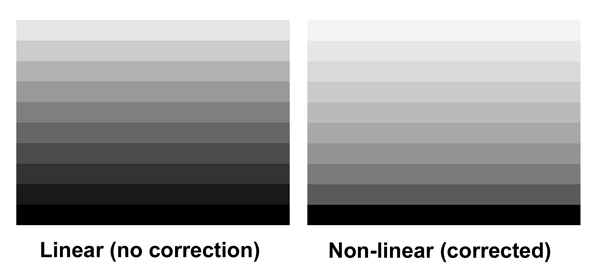

The relevant block in the algo pipe is the DIGG. The operation will be done using a shift, scale and a lut.

**Method**

The calibration process will be easy if it will be done with the normal calibration target:

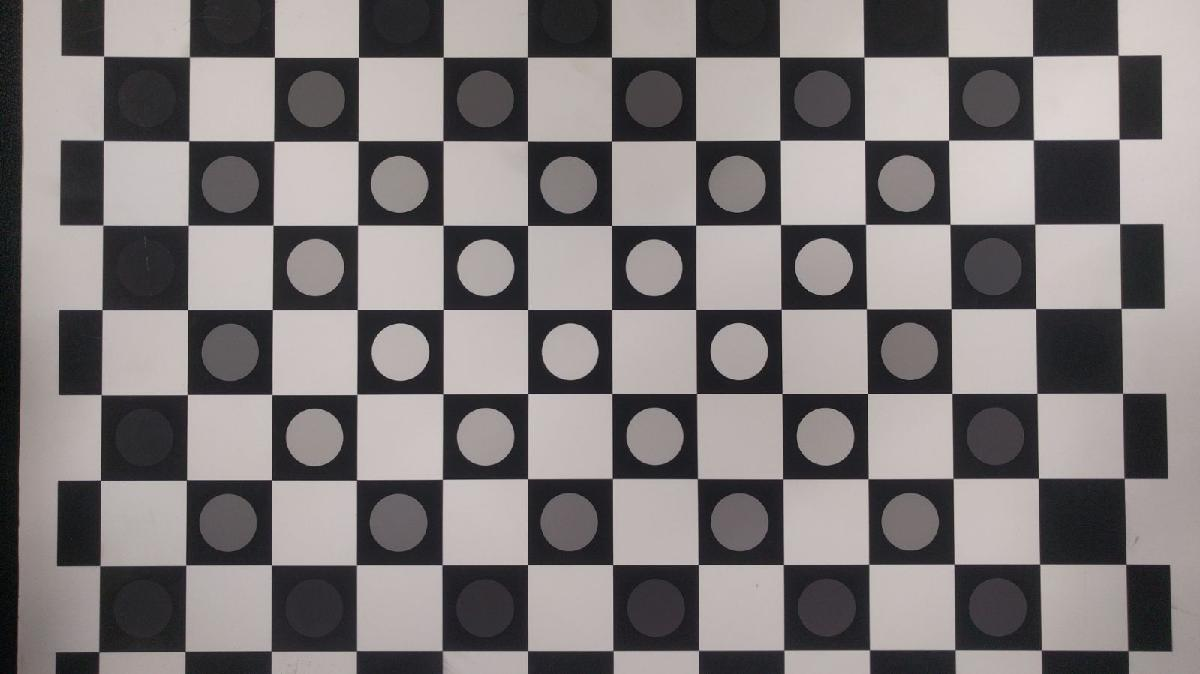

The squares albedo are black and white. The circles (inside the black squares) albedo varies.

For starter, it is interesting to see how different is the intensity curve of the 48 black squares for different cameras. I used nexus 5 cellular device camera, a PointGray IR camera and IVCAM 2. 

For each capture, I find the centers of all black squares, sorted their intensity and plotted their values:

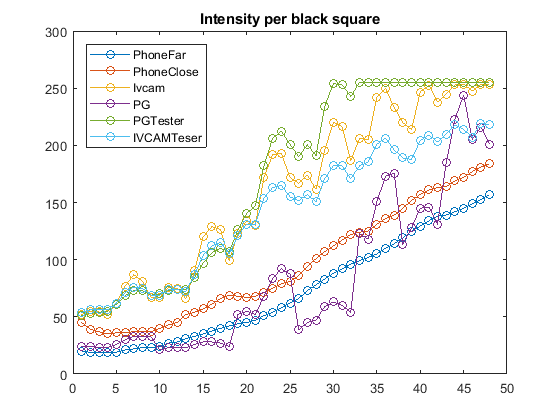


I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBFar.jpg'); 
[~,ccBlackPhoneFar] = DetectBlackCBPointsAndSortedValues(I);


I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBClose.jpg');
[~,ccBlackPhoneClose] = DetectBlackCBPointsAndSortedValues(I);

I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBivcam.jpg');
[~,ccBlackIvcam] = DetectBlackCBPointsAndSortedValues(I);

I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBpointgray.pgm');
[~,ccBlackPG] = DetectBlackCBPointsAndSortedValues(I);

I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\PGStreamNoLightsMax.pgm');
[~,ccBlackPGNoLightsTester] = DetectBlackCBPointsAndSortedValues(I);

I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBTesterFarIvcam.tif');
[~,ccBlackIvcamNoLightsTester] = DetectBlackCBPointsAndSortedValues(I);


figure
plot([ccBlackPhoneFar,ccBlackPhoneClose,ccBlackIvcam,ccBlackPG,ccBlackPGNoLightsTester,ccBlackIvcamNoLightsTester],'-o')
title('Intensity per black square')
legend({'PhoneFar','PhoneClose','Ivcam','PG','PGTester','IVCAMTeser'},'location','northwest');

The IVCAM IR values spans most of the range ([min,max] are [50,250]). While the phone values are almost monotonically increasing and are close to linear, the ivcam and PG recordings seems noisy. The are some reasons that contribue to that phenomenon:

- The phone camera image has already gone through gamma correction. 

- The phone camera probably compensates for [Vignetting](https://en.wikipedia.org/wiki/Vignetting) while ivcam doesn't (The cos^4 illumination fallout).

A suggested approach for calibrating the GAMMA:

- Take the PG image. Use 3d interpolation (x,y,ir) to identify the mapping between the black and white points to their minimal and maximal values. Apply to all pixels.

- Take the IVCAM image. Do the same.  

- Define the scale,shift and lut so each color in the normalized images match. The normalization purpose is to minimize the effect the different lighting (and maybe position) has on the IR images.

## Gamma Correcting

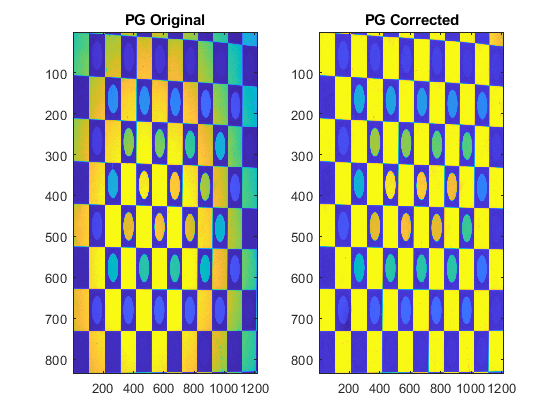

% Load Point Gray Image
Ipg = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBpointgray.pgm');
Ipg = flipud(fliplr(Ipg));
% Get the corners of all squares. For each square, get the pixel values close to the four corners and also the center value for the white squares.  
[ newI,oldV,newV ] = correctCheckerboard( Ipg );
% Load IVCAM Image
Iivcam = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBTesterFarIvcam.tif');
% Get the corners of all squares. For each square, get the pixel values close to the four corners and also the center value for the white squares.  
[ newIivcam,oldVivcam,newVivcam ] = correctCheckerboard( Iivcam );
figure
subplot(1,2,1);
imagesc(oldV), title('PG Original');
subplot(1,2,2);
imagesc(newV), title('PG Corrected');

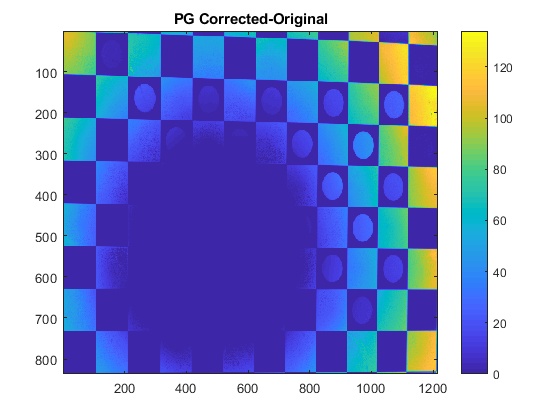

figure;
imagesc(newV-oldV),title('PG Corrected-Original'),colorbar;

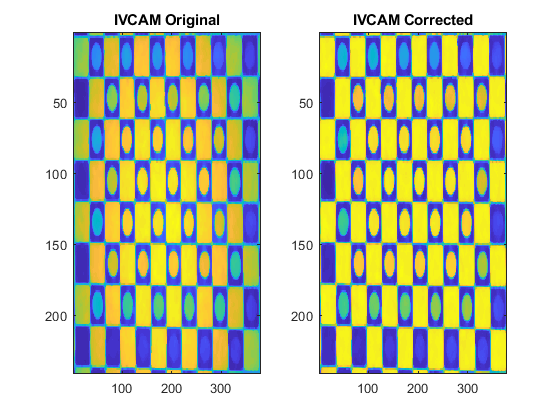


figure
subplot(1,2,1);
imagesc(oldVivcam), title('IVCAM Original');
subplot(1,2,2);
imagesc(newVivcam), title('IVCAM Corrected');

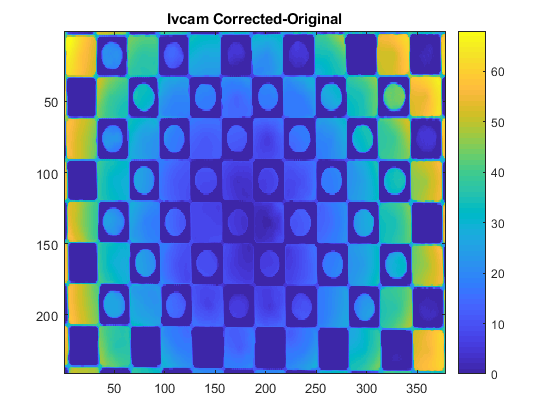

figure;
imagesc(newVivcam-oldVivcam),title('Ivcam Corrected-Original'),colorbar;

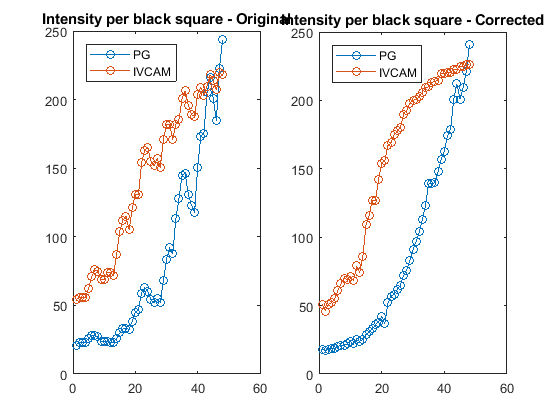


% Now let us have a look at the IR curve of the circles before and after the correction

[~,cpIvcam] = DetectBlackCBPointsAndSortedValues(Iivcam);
[~,cpPG] = DetectBlackCBPointsAndSortedValues(Ipg);
[~,cpIvcamPost] = DetectBlackCBPointsAndSortedValues(newIivcam);
[~,cpPGPost] = DetectBlackCBPointsAndSortedValues(newI);

subplot(1,2,1)
plot([cpPG,cpIvcam],'-o'),title('Intensity per black square - Original')
legend({'PG','IVCAM'},'location','northwest');
subplot(1,2,2)
plot([cpPGPost,cpIvcamPost],'-o'),title('Intensity per black square - Corrected')
legend({'PG','IVCAM'},'location','northwest');

**Experiments**

I shall try apply the correction procedure on two images taken from the same position (Taking an image with the PG and then replacing it with the IVCAM module).